# Análise de controladores

## Boas práticas

clear all;          % limpa as variáveis
clc;                % limpa a tela
close all;          % fecha as figuras abertas


## Diagrama em malha fechada

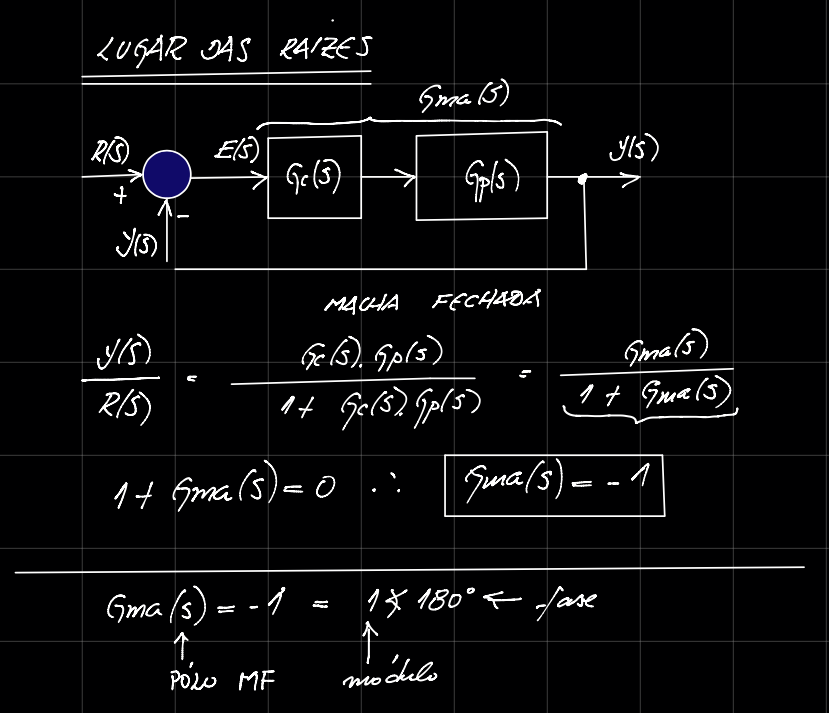

## Sistemas que desejamos analisar

**Projeto de controlador PI**


$$G_p(s) = \frac{1}{s+1}$$



$$G_c(s) = 6.7\frac{s+1.16}{s(s+4.48)}$$


**Projeto de controlador avanço**


$$G_p(s) = \frac{22.47}{s+28.09}$$



$$G_c(s) = 2.31\frac{s+61.65}{s}$$


## Traduzindo para o Matlab

**Sistema 1**


Gc  = tf(6.7*[1 1.16],[1 4.48 0]);
Gp  = tf(1,[1 1]);
Gma = Gc*Gp

Gma =
 
       6.7 s + 7.772
  -----------------------
  s^3 + 5.48 s^2 + 4.48 s
 
Continuous-time transfer function.




[Gm,Pm,Wcg,Wcp] = margin(Gma)

Gm = Inf

Pm = 67.5388

Wcg = Inf

Wcp = 1.4928

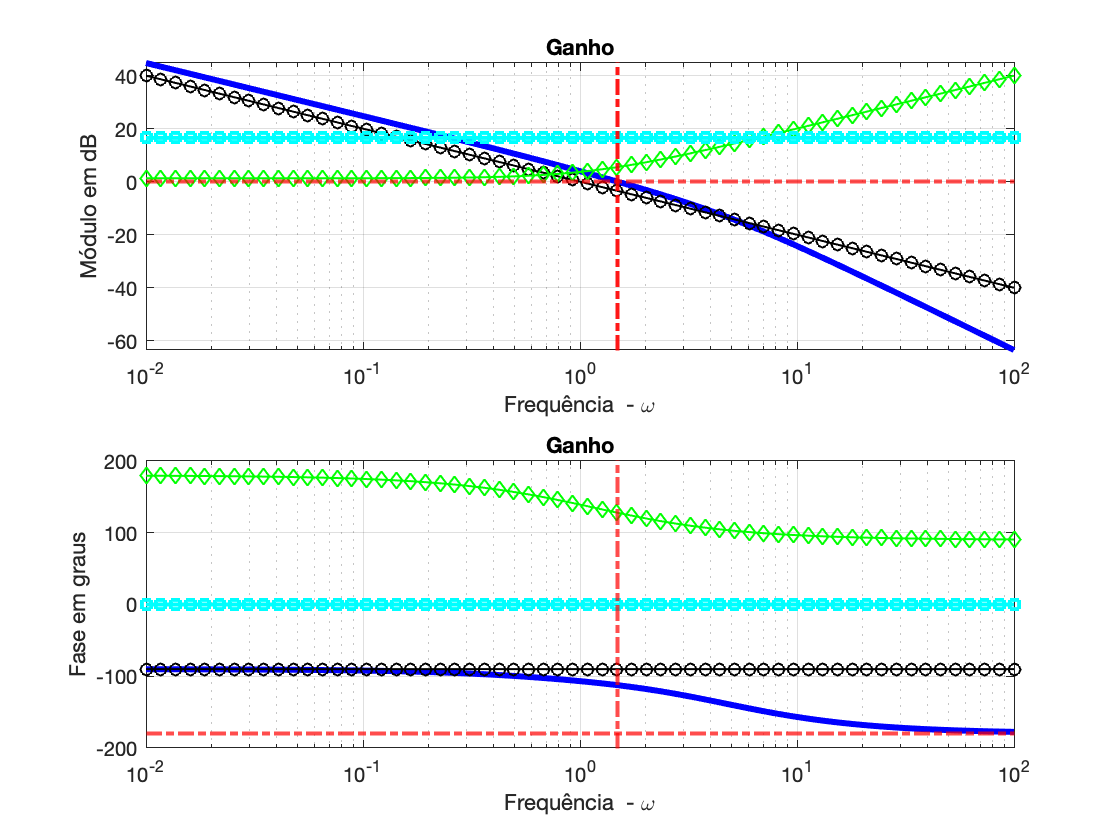

Current plot held


Current plot held




figure()
SegmentaBode(Gma,0.01,100)

**Sistema 2**


Gc  = tf(2.31*[1 61.65],[1 0]);
Gp  = tf(22.47,[1 28.09]);
Gma = Gc*Gp

Gma =
 
  51.91 s + 3200
  --------------
  s^2 + 28.09 s
 
Continuous-time transfer function.




[Gm,Pm,Wcg,Wcp] = margin(Gma)

Gm = Inf

Pm = 69.9477

Wcg = NaN

Wcp = 65.5084

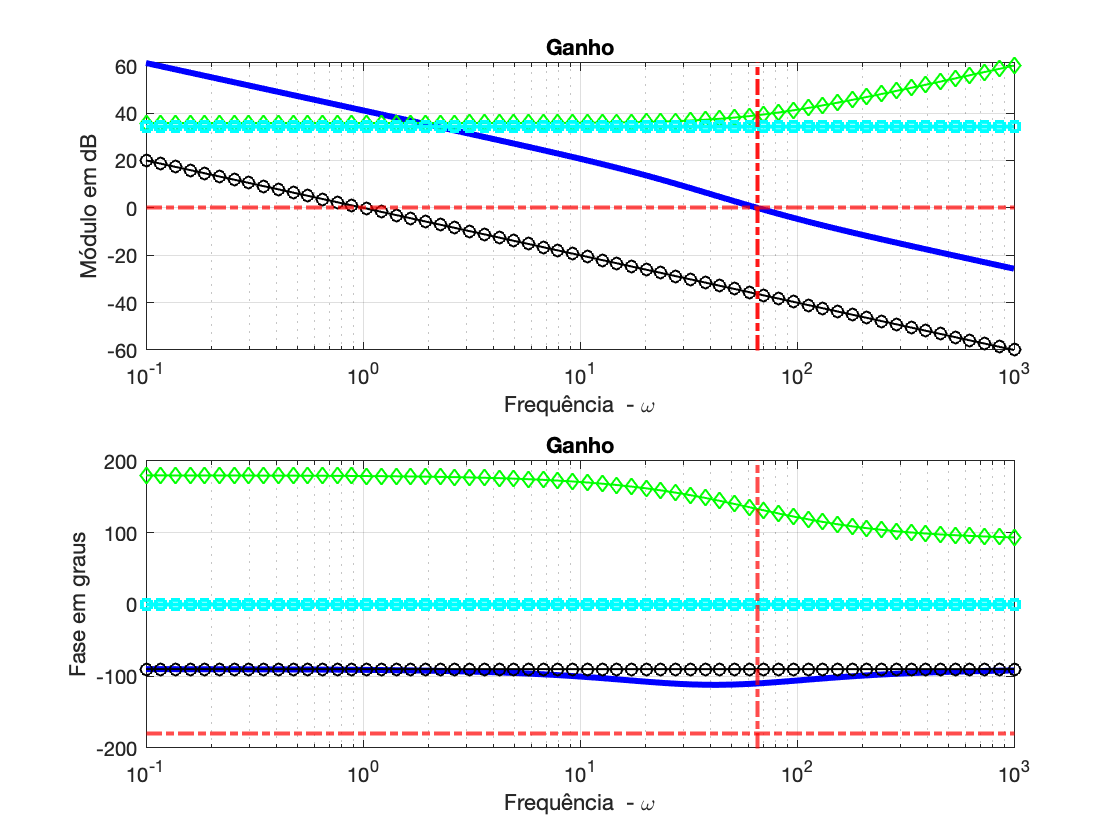

Current plot held


Current plot held




figure()
SegmentaBode(Gma,0.1,1000)